**Business case 4 - Investment Replica**

**Load data**

clear all
close all
path = 'InvestmentReplica.mat';
load(path)

### Data Exploration

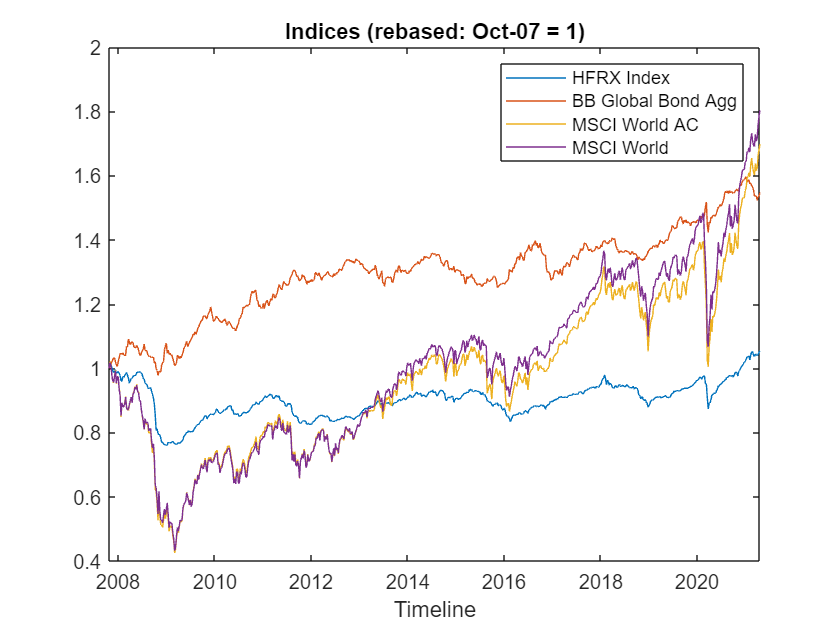

figure
plot(XTab.Date,XTab.HFRXGL/XTab.HFRXGL(1),'DisplayName','HFRX Index');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

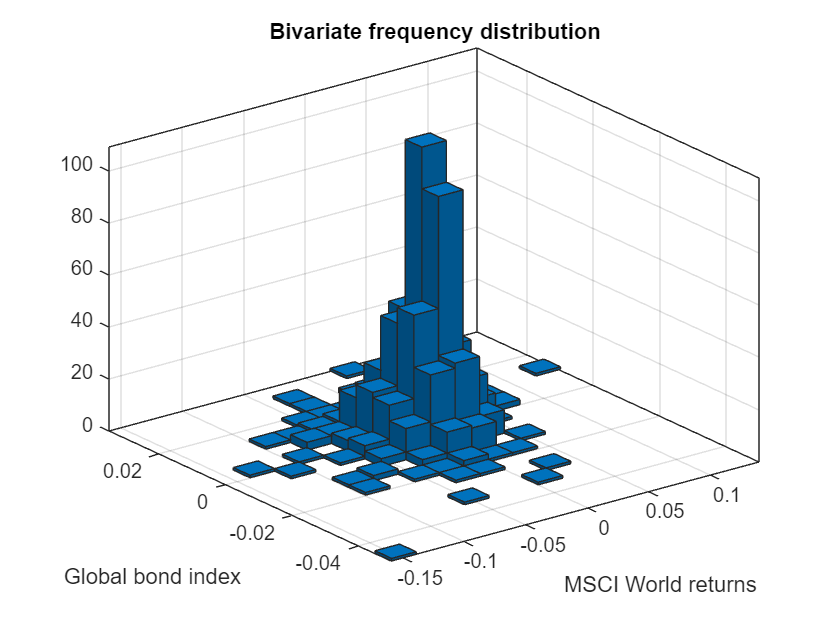

figure
histogram2(price2ret(MXWO),price2ret(LEGATRUU))
xlabel('MSCI World returns')
ylabel('Global bond index')
title('Bivariate frequency distribution')

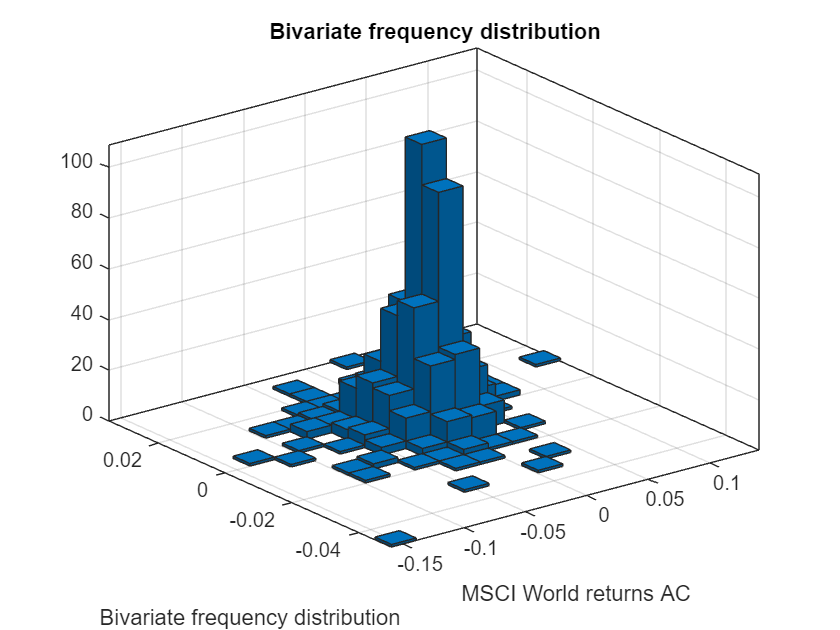


figure
histogram2(price2ret(MXWO),price2ret(LEGATRUU))
xlabel('MSCI World returns AC')
ylabel('Bivariate frequency distribution')
title('Bivariate frequency distribution')

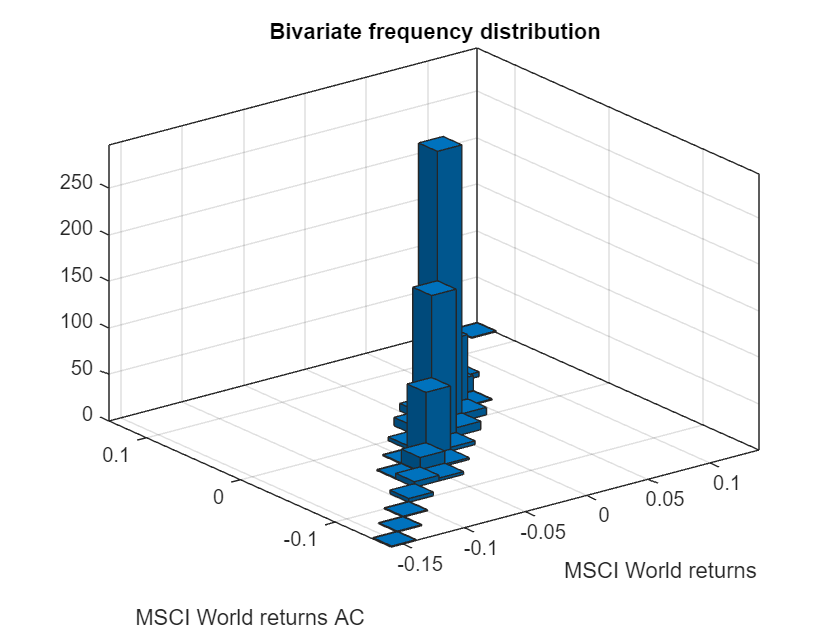


figure
histogram2(price2ret(MXWO),price2ret(MXWD))
xlabel('MSCI World returns')
ylabel('MSCI World returns AC')
title('Bivariate frequency distribution')

Sottolineare correlazione tra gli MSCI

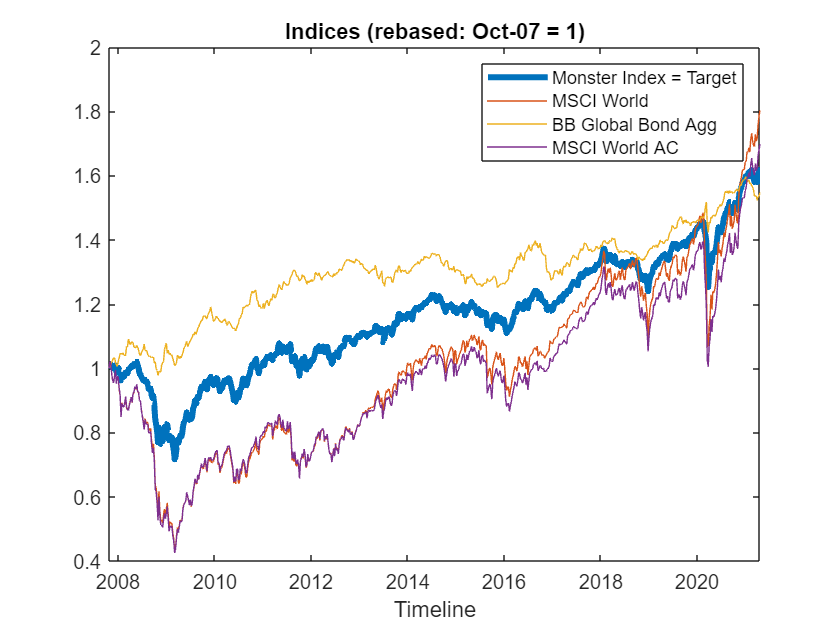

% Synthetic target weights
wMXWO = 0.2; 
wMXWD = 0.2;
wLEGATRUU = 0.6;
%Primi due simili

% Building the target
y = wMXWD*price2ret(MXWD) + wMXWO*price2ret(MXWO) + wLEGATRUU*price2ret(LEGATRUU); % "Monster Index" returns
target = (ret2price(y)); % "Monster Index" levels

figure
p = plot(XTab.Date,target,'DisplayName','Monster Index = Target');
p.LineWidth = 3;
hold on;
plot(XTab.Date,XTab.MXWO/XTab.MXWO(1),'DisplayName','MSCI World');
hold on;
plot(XTab.Date,XTab.LEGATRUU/XTab.LEGATRUU(1),'DisplayName','BB Global Bond Agg');
plot(XTab.Date,XTab.MXWD/XTab.MXWD(1),'DisplayName','MSCI World AC');
xlabel('Timeline')
title('Indices (rebased: Oct-07 = 1)')
legend
hold off;

Commento confronto andamento singoli indici e monster. 

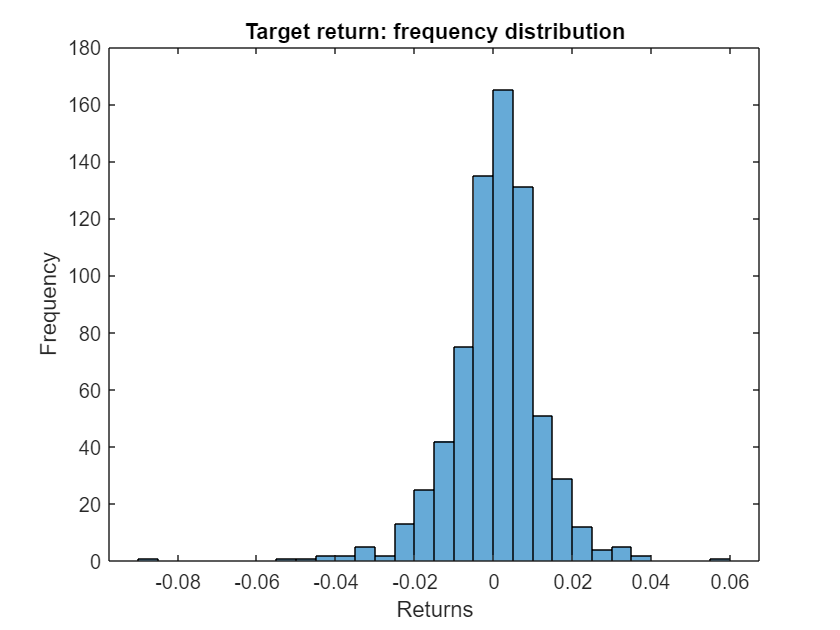

figure
histogram(y)
title('Target return: frequency distribution')
ylabel('Frequency')
xlabel('Returns')

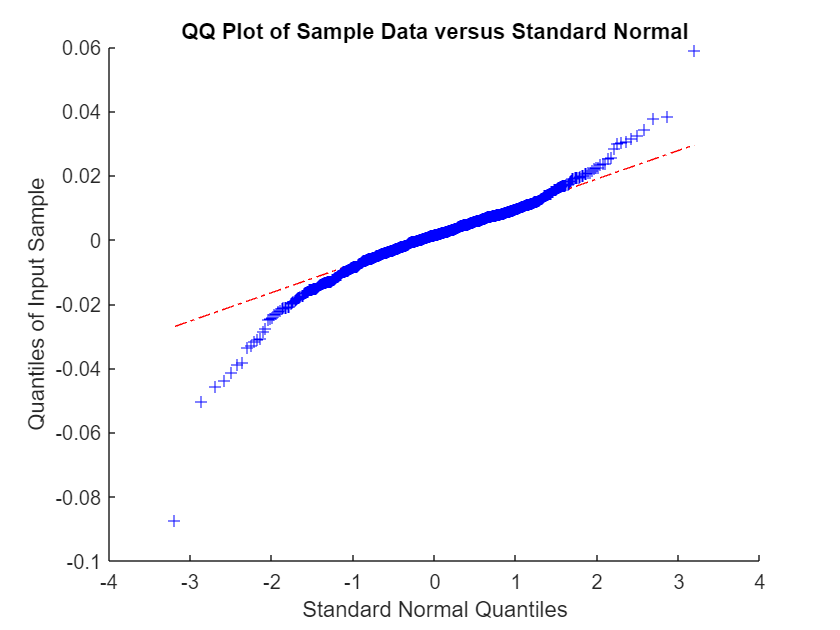


figure
qqplot(y)

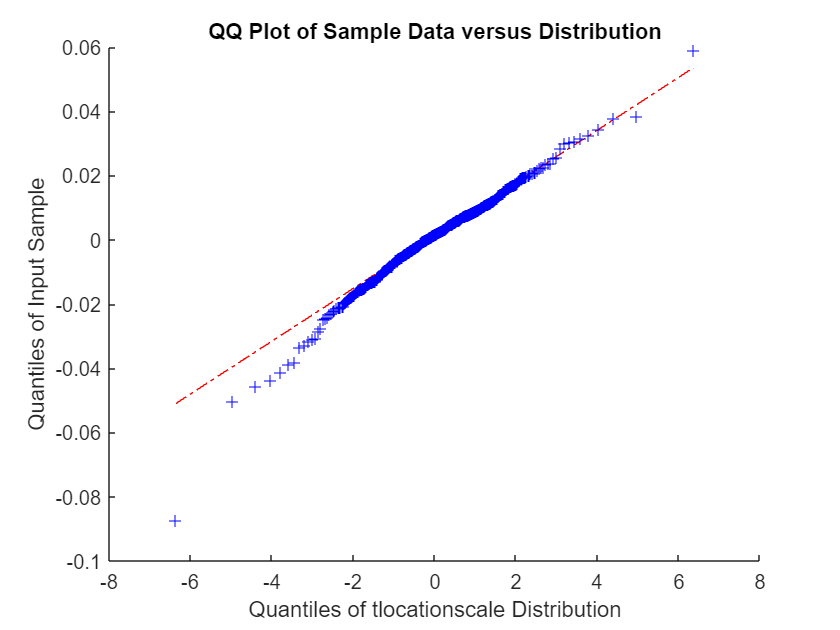


figure
qqplot(y, makedist("tLocationScale"))

Vogliamo replicare coi futures

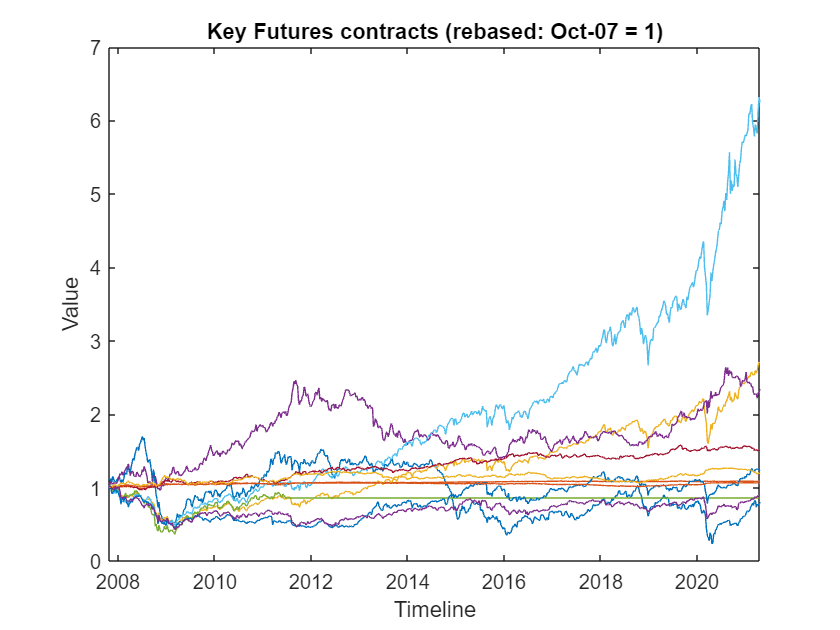

% Futures returns
X = [price2ret(CO1) price2ret(DU1) price2ret(ES1) price2ret(GC1)...
           price2ret(LLL1) price2ret(NQ1) price2ret(RX1) price2ret(TP1)...
           price2ret(TU2) price2ret(TY1) price2ret(VG1)];

figure
plot(XTab.Date, ret2price(X))
xlabel('Timeline')
ylabel('Value')
title('Key Futures contracts (rebased: Oct-07 = 1)')

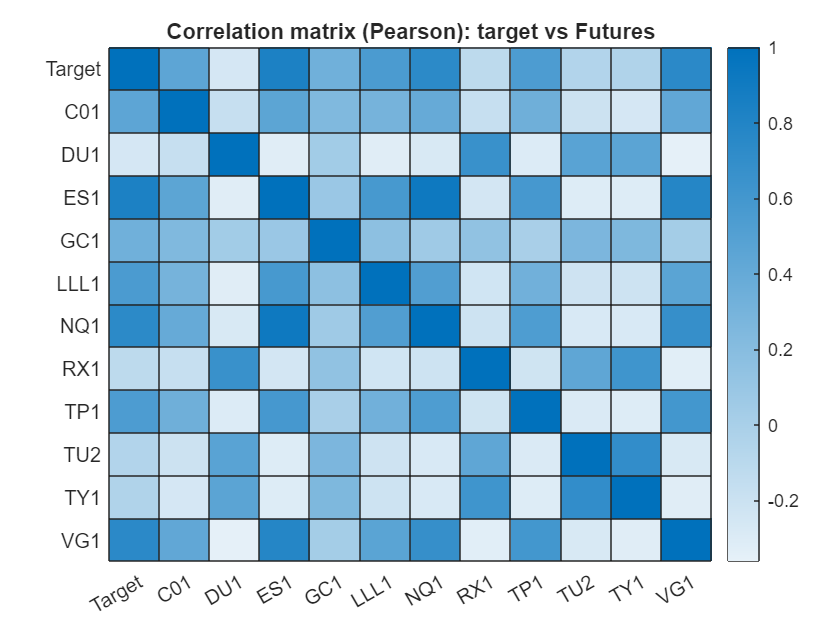

figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Pearson'));
h.Title = 'Correlation matrix (Pearson): target vs Futures';

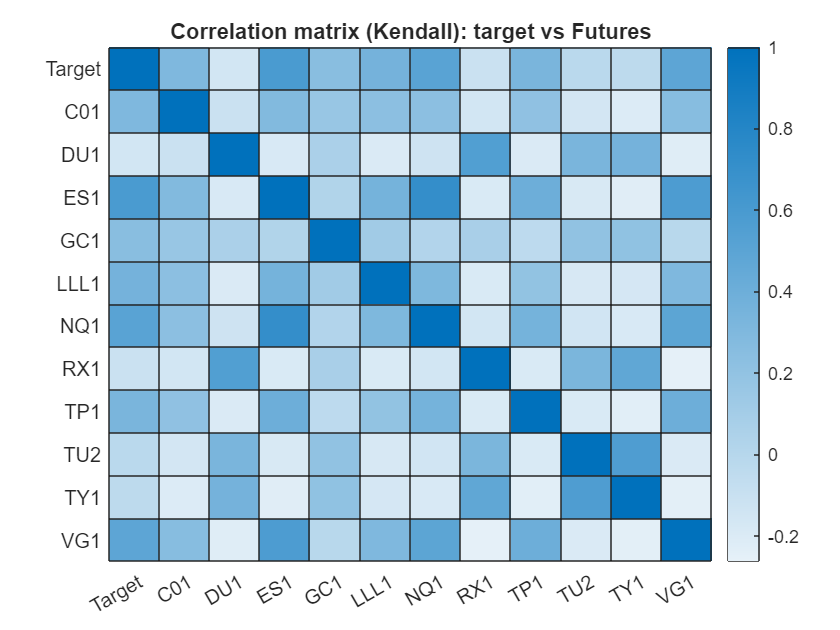


figure
yvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
xvalues = {'Target','C01','DU1','ES1','GC1','LLL1','NQ1','RX1','TP1','TU2','TY1','VG1'};
h = heatmap(xvalues,yvalues,corr([y X],'type', 'Kendall'));
h.Title = 'Correlation matrix (Kendall): target vs Futures';

Si può fare: RSI e Median

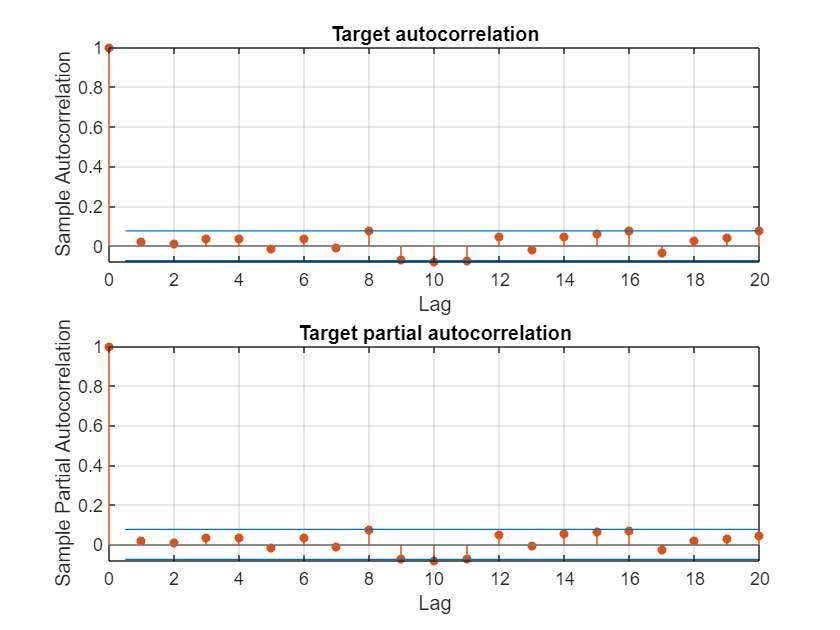

figure
subplot(2,1,1)
autocorr(y)
title('Target autocorrelation')
subplot(2,1,2)
parcorr(y)
title('Target partial autocorrelation')

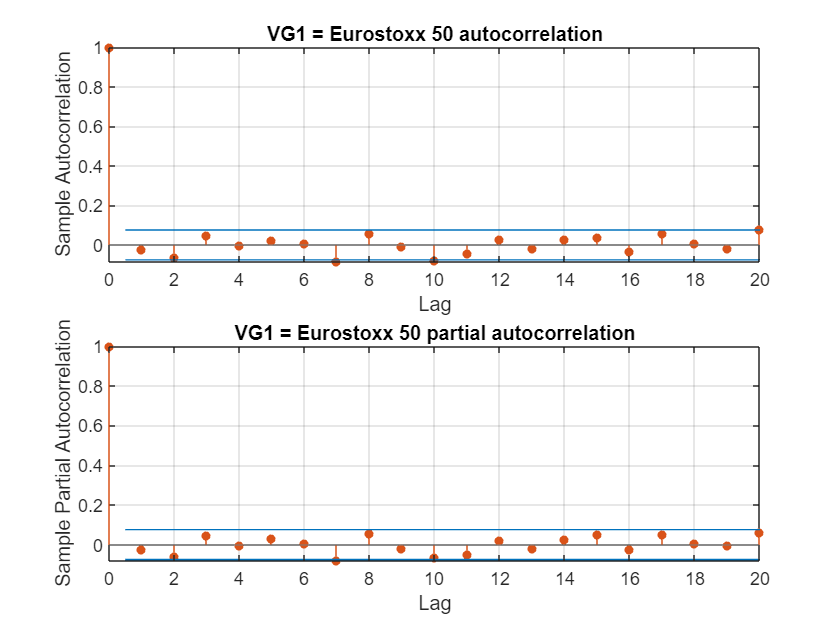

figure
subplot(2,1,1)
autocorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 autocorrelation')
subplot(2,1,2)
parcorr(price2ret(VG1))
title('VG1 = Eurostoxx 50 partial autocorrelation')

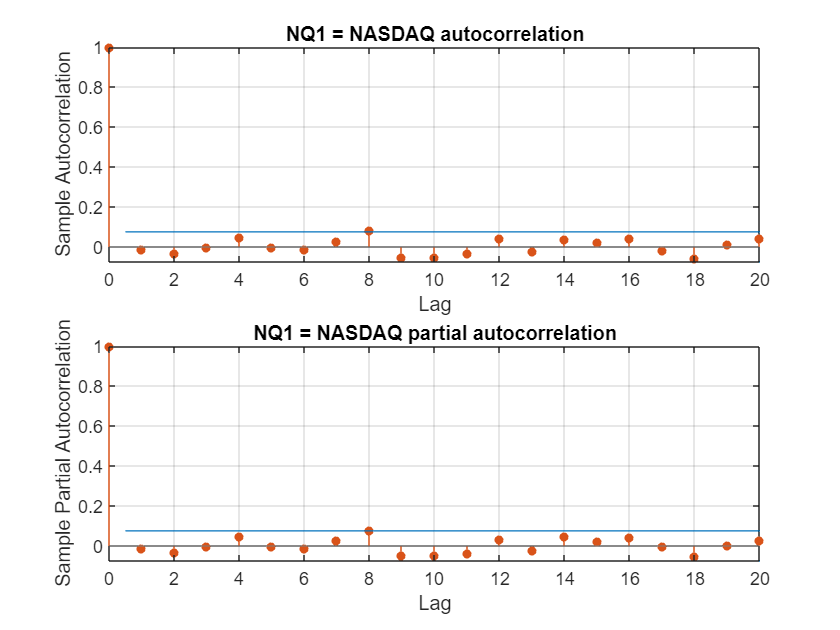

figure
subplot(2,1,1)
autocorr(price2ret(NQ1))
title('NQ1 = NASDAQ autocorrelation')
subplot(2,1,2)
parcorr(price2ret(NQ1))
title('NQ1 = NASDAQ partial autocorrelation')

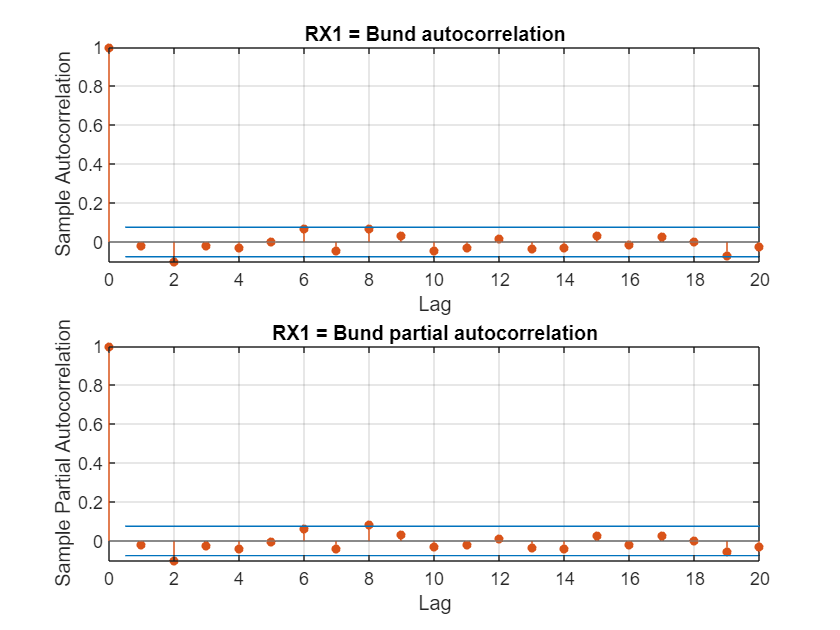

figure
subplot(2,1,1)
autocorr(price2ret(RX1))
title('RX1 = Bund autocorrelation')
subplot(2,1,2)
parcorr(price2ret(RX1))
title('RX1 = Bund partial autocorrelation')

% in weeks (52 = 1Y, 104 = 2Y...)
%Si possono fare confronti cambiando la rolling window e alpha e
%confrontando con un algoritmo ad alpha mobile

%rw 104 156 208 260 + alpha 0.05 0.5 0.95
rollingWindows = [104, 156, 208, 260];
alphas = [0.05, 0.5, 0.95];
% create the variables as cellmatrices to store the results
bEnet2s = cell(length(rollingWindows), length(alphas));
rEnet2s = cell(length(rollingWindows), length(alphas));
GrossExposures = cell(length(rollingWindows), length(alphas));

warning('off','all'); % avoid annoying warnings during the loops
for i = 1:length(rollingWindows)
    for j = 1:length(alphas)

        %create the variables for the current combination
        k = 1;
        rollingWindow = rollingWindows(i);
        alpha = alphas(j);
        b = []; bEnet2 = []; rEnet2 = []; GrossExposure = [];
        endSample = 0;

        % do the usual while loop but using k instead of i
        while endSample <= (length(X)-2)
            startSample = k; endSample = k+rollingWindow-1;
            % compute the lasso regression
            [b,fitinfo] = lasso(X(startSample:endSample,:),y(startSample:endSample),'Alpha',alpha,'CV',5, 'Intercept',false);
            % lambda half-way between MinMSE and 1SE away from MinMSE
            lam = round((fitinfo.Index1SE + fitinfo.IndexMinMSE)/2);
            b = b(:,lam);
            GrossExposure = [GrossExposure; sum(abs(b))];
            bEnet2 = [bEnet2; b'];
            r = X(endSample + 1,:)*b;
            rEnet2 = [rEnet2; r];
            k = k+1;
        end

        % save the data into the variables by adding a cell (this is due to the
        % fact that the arrays are all of differings legths)
        % we don't save b since we already store the important bits in bEnet2
        bEnet2s{i,j} = bEnet2;
        rEnet2s{i,j} = rEnet2;
        GrossExposures{i,j} = GrossExposure;
    end
end

warning('on','all'); % warnings on again

**Financial statistics**

TEV -> Per confronto 

% create matrices with same dimensions as rEnet2s
TEV = zeros(size(rEnet2s));
meanTRTarget = zeros(size(rEnet2s)); meanTRClone = zeros(size(rEnet2s)); meanER = zeros(size(rEnet2s));
IR = zeros(size(rEnet2s));
meanTurnover = zeros(size(rEnet2s)); meanTradingCosts = zeros(size(rEnet2s));
NetER = zeros(size(rEnet2s)); NetTR = zeros(size(rEnet2s)); NetIR = zeros(size(rEnet2s));

for i = 1:length(rollingWindows)
    % get the rollingwindow
    rollingWindow = rollingWindows(i);
    for j = 1:length(alphas)
        rEnet2 = rEnet2s{i,j};
        bEnet2 = bEnet2s{i,j};
        % tracking error and tracking error volatility
        TE = rEnet2 - y(rollingWindow + 1: end); 
        TEV(i,j) = std(TE)*sqrt(52);
        % mean excess return
        logRClone = diff(log(ret2price(rEnet2)));
        logRTarget = diff(log(ret2price(y(rollingWindow + 1: end))));
        logTE =  logRClone - logRTarget;
        meanTRTarget(i,j) = exp(mean(logRTarget)*52) - 1;
        meanTRClone(i,j) = exp(mean(logRClone)*52) - 1;
        meanER(i,j) = exp(mean(logTE)*52) - 1;
        % Information Ratio
        IR(i,j) = meanER(i,j)/TEV(i,j);
        % turnover
        Turnover = calcTurnover(bEnet2); % weekly turnover
        meanTurnover(i,j) = mean(Turnover)*52; % average annual turnover
        tradingCosts = 0.0004; % transaction costs (hp: buyCosts=sellCost)
        meanTradingCosts(i,j) = meanTurnover(i,j)*tradingCosts;
        % Net ER
        NetTR(i,j) = meanTRClone(i,j) - meanTradingCosts(i,j); % transaction costs (hp: buyCosts=sellCost)
        NetER(i,j) = meanER(i,j) - meanTradingCosts(i,j);
        NetIR(i,j) = NetER(i,j)/TEV(i,j);
    end
end
disp(TEV)

    0.0350    0.0342    0.0342
    0.0334    0.0330    0.0334
    0.0322    0.0315    0.0317
    0.0329    0.0323    0.0321



disp(meanTRTarget)

    0.0468    0.0468    0.0468
    0.0462    0.0462    0.0462
    0.0504    0.0504    0.0504
    0.0472    0.0472    0.0472



disp(meanTRClone)

    0.0472    0.0452    0.0447
    0.0464    0.0464    0.0439
    0.0489    0.0487    0.0473
    0.0441    0.0435    0.0422



disp(meanER)

    0.0004   -0.0015   -0.0020
    0.0002    0.0003   -0.0022
   -0.0014   -0.0016   -0.0029
   -0.0029   -0.0035   -0.0047



disp(IR)

    0.0128   -0.0451   -0.0593
    0.0059    0.0080   -0.0647
   -0.0430   -0.0519   -0.0926
   -0.0897   -0.1082   -0.1475



disp(NetER)

   -0.0017   -0.0060   -0.0079
   -0.0015   -0.0037   -0.0072
   -0.0030   -0.0052   -0.0073
   -0.0047   -0.0069   -0.0085



Gross

In generale, un buon risultato in un portafoglio di replica dovrebbe essere caratterizzato da un ER positivo, una volatilità limitata e una bassa correlazione con il benchmark di riferimento. Un portafoglio che ottiene un ER positivo ma con una volatilità elevata potrebbe essere più rischioso di quanto sia accettabile, mentre un portafoglio con un ER negativo ma una bassa volatilità potrebbe essere considerato accettabile se offre una buona protezione dal rischio.

Quando l'ER del portafoglio di replica è più alto del target, significa che il portafoglio di replica ha generato un rendimento superiore rispetto all'indice di riferimento, ovvero il portafoglio target. In altre parole, il portafoglio di replica ha aggiunto valore rispetto all'indice di riferimento.

Ci possono essere diverse ragioni per cui ciò accade. Ad esempio, il gestore del portafoglio di replica potrebbe aver selezionato titoli o strategie di investimento che hanno reso meglio rispetto a quelli del portafoglio target. 

Tuttavia, è importante valutare anche altri fattori oltre all'ER per determinare se il risultato del portafoglio di replica è effettivamente positivo. Ad esempio, è importante considerare la volatilità del portafoglio, la diversificazione e il rischio complessivo del portafoglio.

% get the best combinations by getting the max Net ER
maxNetER = max(max(NetER))

maxNetER = -0.0015

[Mi, Mj] = find(NetER == maxNetER);
rollingWindow = rollingWindows(Mi);
rEnet2 = rEnet2s{Mi,Mj};
GrossExposure = GrossExposures{Mi,Mj};

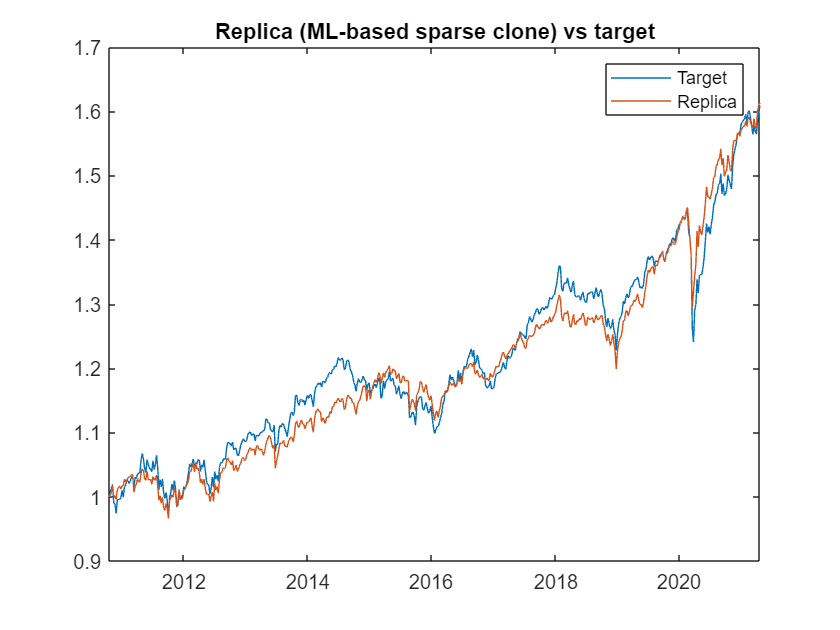

figure
plot(Date(rollingWindow+1:end),ret2price(y(rollingWindow + 1: end)),'DisplayName','Target');
hold on;
plot(Date(rollingWindow+1:end),ret2price(rEnet2),'DisplayName','Replica');
legend
title('Replica (ML-based sparse clone) vs target')
hold off;

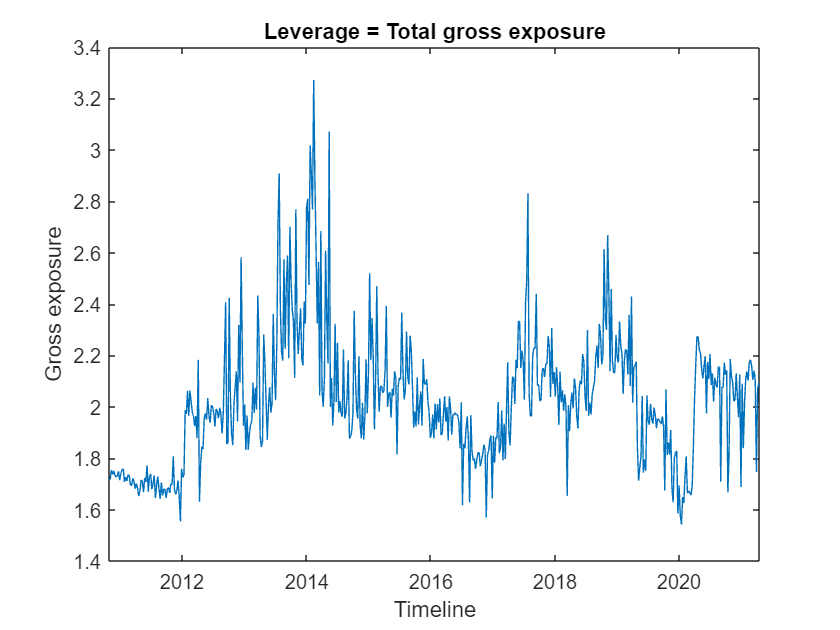

figure
plot(Date(rollingWindow+2:end),GrossExposure+1); % add 1 for your collateral + margins
title('Leverage = Total gross exposure')
xlabel('Timeline')
ylabel('Gross exposure')
hold off;